clear all
clc;
syms qs qg q_dot_s q_dot_g q_dot_dot_s q_dot_dot_g real;
syms T
syms a b c d e f tau


q_dot_g = 0;
q_dot_dot_s = 0;
q_dot_dot_g = 0;

% x = (a, 
%      b, 
%      c, 
%      d, 
%      e,
%      f)



% A = q(0)  WITHOUTH TERMINI NOTI   
%     q(1) 
%     q_dot(0) 
%     q_dot(1) 
%     q_dot_dot(0) 
%     q_dot_dot(1)


A = [0, 0, 0, 0, 0, 1;
     1, 1, 1, 1, 1, 1;
     0, 0, 0, 0, 1, 0;
     5, 4, 3, 2, 1, 0;
     0, 0, 0, 2, 0, 0;
     20, 12, 6, 2, 0, 0;]

A =      0     0     0     0     0     1
     1     1     1     1     1     1
     0     0     0     0     1     0
     5     4     3     2     1     0
     0     0     0     2     0     0
    20    12     6     2     0     0




B = [qs;
     qg;
     q_dot_s*T
     q_dot_g
     q_dot_dot_s*T^2
     q_dot_dot_g*T^2
     ]

$$B = \left(\begin{array}{c} \mathrm{qs}\\ \mathrm{qg}\\ T\,{\dot{q}}_{s}\\ 0\\ 0\\ 0 \end{array}\right)$$


x = simplify(A\B, steps=100)

$$x = \left(\begin{array}{c} 6\,\mathrm{qg}-6\,\mathrm{qs}-3\,T\,{\dot{q}}_{s}\\ 15\,\mathrm{qs}-15\,\mathrm{qg}+8\,T\,{\dot{q}}_{s}\\ 10\,\mathrm{qg}-10\,\mathrm{qs}-6\,T\,{\dot{q}}_{s}\\ 0\\ T\,{\dot{q}}_{s}\\ \mathrm{qs} \end{array}\right)$$



x_q1 = subs(x, [qs, qg, q_dot_s, T], [-pi/4, 0, 2.8284, 2])

$$x\_q1 = \left(\begin{array}{c} -12.2580\\ 33.4734\\ -26.0868\\ 0\\ 5.6568\\ -0.7854 \end{array}\right)$$

x_q2 = subs(x, [qs, qg, q_dot_s, T], [pi/4, 0, -8.4853, 2])

$$x\_q2 = \left(\begin{array}{c} 46.1994\\ -123.9838\\ 93.9696\\ 0\\ -16.9706\\ 0.7854 \end{array}\right)$$

x_q3 = subs(x, [qs, qg, q_dot_s, T], [pi/4, pi/4, 0, 2])

$$x\_q3 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0.7854 \end{array}\right)$$


q_tau = a*tau^5 + b*tau^4 + c*tau^3 + d*tau^2 + e*tau + f

$$q\_tau = a\,\tau^{5}+b\,\tau^{4}+c\,\tau^{3}+d\,\tau^{2}+e\,\tau +f$$

q_tau_q1 = subs(q_tau, [a, b, c, d, e, f], x_q1.')

$$q\_tau\_q1 = -12.2580\,\tau^{5}+33.4734\,\tau^{4}-26.0868\,\tau^{3}+5.6568\,\tau -0.7854$$

q_tau_q2 = subs(q_tau, [a, b, c, d, e, f], x_q2.')

$$q\_tau\_q2 = 46.1994\,\tau^{5}-123.9838\,\tau^{4}+93.9696\,\tau^{3}-16.9706\,\tau +0.7854$$

q_tau_q3 = subs(q_tau, [a, b, c, d, e, f], x_q3.')

$$q\_tau\_q3 = 0.7854$$


q_tau_dot = (1/T)*(5*a*tau^4 + 4*b*tau^3 + 3*c*tau^2 + 2*d*tau + e)

$$q\_tau\_dot = \frac{5\,a\,\tau^{4}+4\,b\,\tau^{3}+3\,c\,\tau^{2}+2\,d\,\tau +e}{T}$$

q_tau_dot_q1 = subs(q_tau_dot, [a, b, c, d, e, f, T], [x_q1.', 2])

$$q\_tau\_dot\_q1 = -30.6450\,\tau^{4}+66.9469\,\tau^{3}-39.1302\,\tau^{2}+2.8284$$

q_tau_dot_q2 = subs(q_tau_dot, [a, b, c, d, e, f, T], [x_q2.', 2])

$$q\_tau\_dot\_q2 = 115.4985\,\tau^{4}-247.9677\,\tau^{3}+140.9544\,\tau^{2}-8.4853$$

q_tau_dot_q3 = subs(q_tau_dot, [a, b, c, d, e, f, T], [x_q3.', 2])

$$q\_tau\_dot\_q3 = 0$$


q_tau_dot_dot = (1/T^2)*(20*a*tau^3 + 12*b*tau^2 + 6*c*tau + 2*d)

$$q\_tau\_dot\_dot = \frac{20\,a\,\tau^{3}+12\,b\,\tau^{2}+6\,c\,\tau +2\,d}{T^{2}}$$

q_tau_dot_dot_q1 = subs(q_tau_dot_dot, [a, b, c, d, e, f, T], [x_q1.', 2])

$$q\_tau\_dot\_dot\_q1 = -61.2901\,\tau^{3}+100.4203\,\tau^{2}-39.1302\,\tau$$

q_tau_dot_dot_q2 = subs(q_tau_dot_dot, [a, b, c, d, e, f, T], [x_q2.', 2])

$$q\_tau\_dot\_dot\_q2 = 230.9971\,\tau^{3}-371.9515\,\tau^{2}+140.9544\,\tau$$

q_tau_dot_dot_q3 = subs(q_tau_dot_dot, [a, b, c, d, e, f, T], [x_q3.', 2])

$$q\_tau\_dot\_dot\_q3 = 0$$

## Plot the result

% Generate time values (tau)
tau_values = linspace(0, 1, 100);

% Compute the expressions q_tau_q1, q_tau_q2, and q_tau_q3
q_tau_q1_values = subs(q_tau_q1, tau, tau_values)

$$q\_tau\_q1\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} -0.7854 & -0.7283 & -0.6713 & -0.6147 & -0.5585 & -0.5028 & -0.4479 & -0.3938 & -0.3407 & -0.2885 & -0.2375 & -0.1878 & -0.1393 & -0.0922 & -0.0465 & -0.0024 & 0.0402 & 0.0812 & 0.1205 & 0.1581 & 0.1939 & 0.2280 & 0.2604 & 0.2909 & 0.3196 & 0.3465 & 0.3716 & 0.3949 & 0.4163 & 0.4360 & 0.4538 & 0.4699 & 0.4842 & 0.4968 & 0.5077 & 0.5170 & 0.5246 & 0.5306 & 0.5351 & 0.5381 & 0.5396 & 0.5397 & 0.5384 & 0.5359 & 0.5320 & 0.5270 & 0.5209 & 0.5136 & 0.5054 & 0.4961 & 0.4860 & 0.4751 & 0.4633 & 0.4509 & 0.4378 & 0.4242 & 0.4100 & 0.3954 & 0.3804 & 0.3651 & 0.3495 & 0.3338 & 0.3179 & 0.3019 & 0.2859 & 0.2700 & 0.2542 & 0.2385 & 0.2231 & 0.2079 & 0.1930 & 0.1784 & 0.1643 & 0.1506 & 0.1374 & 0.1247 & 0.1125 & 0.1009 & 0.0899 & 0.0796 & 0.0699 & 0.0608 & 0.0524 & 0.0447 & 0.0377 & 0.0313 & 0.0257 & 0.0206 & 0.0162 & 0.0125 & 0.0093 & 0.0067 & 0.0045 & 0.0029 & 0.0017 & 9.0162e-04 & 3.8794e-04 & 1.1721e-04 & 1.4937e-05 & 0 \end{array}\right)$$

q_tau_q2_values = subs(q_tau_q2, tau, tau_values)

$$q\_tau\_q2\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0.7854 & 0.6141 & 0.4433 & 0.2736 & 0.1056 & -0.0604 & -0.2238 & -0.3843 & -0.5415 & -0.6950 & -0.8444 & -0.9894 & -1.1298 & -1.2654 & -1.3957 & -1.5207 & -1.6401 & -1.7538 & -1.8617 & -1.9635 & -2.0592 & -2.1487 & -2.2319 & -2.3089 & -2.3794 & -2.4436 & -2.5015 & -2.5529 & -2.5981 & -2.6371 & -2.6698 & -2.6964 & -2.7170 & -2.7317 & -2.7405 & -2.7437 & -2.7414 & -2.7337 & -2.7208 & -2.7028 & -2.6800 & -2.6525 & -2.6205 & -2.5842 & -2.5438 & -2.4996 & -2.4518 & -2.4005 & -2.3461 & -2.2887 & -2.2286 & -2.1660 & -2.1012 & -2.0343 & -1.9658 & -1.8957 & -1.8243 & -1.7519 & -1.6787 & -1.6050 & -1.5309 & -1.4567 & -1.3827 & -1.3090 & -1.2359 & -1.1636 & -1.0922 & -1.0221 & -0.9533 & -0.8861 & -0.8206 & -0.7569 & -0.6954 & -0.6360 & -0.5789 & -0.5243 & -0.4722 & -0.4228 & -0.3761 & -0.3322 & -0.2912 & -0.2530 & -0.2178 & -0.1855 & -0.1561 & -0.1296 & -0.1059 & -0.0850 & -0.0668 & -0.0512 & -0.0381 & -0.0273 & -0.0186 & -0.0120 & -0.0071 & -0.0037 & -0.0016 & -4.7726e-04 & -6.0757e-05 & 0 \end{array}\right)$$

q_tau_q3_values = subs(q_tau_q3, tau, tau_values)

$$q\_tau\_q3\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 & 0.7854 \end{array}\right)$$


q_tau_dot_q1_values = subs(q_tau_dot_q1, tau, tau_values)

$$q\_tau\_dot\_q1\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 2.8284 & 2.8245 & 2.8130 & 2.7943 & 2.7689 & 2.7370 & 2.6992 & 2.6557 & 2.6069 & 2.5532 & 2.4950 & 2.4325 & 2.3661 & 2.2961 & 2.2229 & 2.1468 & 2.0680 & 1.9869 & 1.9037 & 1.8188 & 1.7323 & 1.6446 & 1.5560 & 1.4666 & 1.3767 & 1.2866 & 1.1964 & 1.1064 & 1.0168 & 0.9278 & 0.8397 & 0.7525 & 0.6665 & 0.5818 & 0.4986 & 0.4171 & 0.3374 & 0.2597 & 0.1840 & 0.1106 & 0.0395 & -0.0291 & -0.0952 & -0.1587 & -0.2194 & -0.2773 & -0.3323 & -0.3843 & -0.4333 & -0.4793 & -0.5221 & -0.5619 & -0.5984 & -0.6318 & -0.6619 & -0.6888 & -0.7126 & -0.7331 & -0.7505 & -0.7647 & -0.7759 & -0.7839 & -0.7889 & -0.7910 & -0.7901 & -0.7865 & -0.7800 & -0.7710 & -0.7593 & -0.7452 & -0.7287 & -0.7100 & -0.6892 & -0.6665 & -0.6418 & -0.6156 & -0.5877 & -0.5585 & -0.5281 & -0.4967 & -0.4645 & -0.4317 & -0.3984 & -0.3649 & -0.3314 & -0.2981 & -0.2652 & -0.2331 & -0.2019 & -0.1720 & -0.1434 & -0.1167 & -0.0919 & -0.0694 & -0.0496 & -0.0326 & -0.0188 & -0.0086 & -0.0022 & 0 \end{array}\right)$$

q_tau_dot_q2_values = subs(q_tau_dot_q2, tau, tau_values)

$$q\_tau\_dot\_q2\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} -8.4853 & -8.4712 & -8.4298 & -8.3627 & -8.2712 & -8.1570 & -8.0212 & -7.8654 & -7.6908 & -7.4988 & -7.2907 & -7.0677 & -6.8310 & -6.5819 & -6.3216 & -6.0511 & -5.7716 & -5.4841 & -5.1898 & -4.8897 & -4.5847 & -4.2759 & -3.9641 & -3.6503 & -3.3354 & -3.0202 & -2.7055 & -2.3922 & -2.0811 & -1.7727 & -1.4680 & -1.1675 & -0.8719 & -0.5818 & -0.2978 & -0.0205 & 0.2495 & 0.5118 & 0.7659 & 1.0113 & 1.2477 & 1.4745 & 1.6915 & 1.8983 & 2.0947 & 2.2802 & 2.4548 & 2.6181 & 2.7700 & 2.9103 & 3.0388 & 3.1555 & 3.2604 & 3.3532 & 3.4341 & 3.5031 & 3.5601 & 3.6052 & 3.6386 & 3.6604 & 3.6707 & 3.6697 & 3.6576 & 3.6347 & 3.6012 & 3.5574 & 3.5037 & 3.4405 & 3.3680 & 3.2867 & 3.1971 & 3.0996 & 2.9947 & 2.8830 & 2.7651 & 2.6414 & 2.5127 & 2.3795 & 2.2426 & 2.1026 & 1.9603 & 1.8164 & 1.6718 & 1.5272 & 1.3835 & 1.2416 & 1.1023 & 0.9667 & 0.8357 & 0.7102 & 0.5912 & 0.4800 & 0.3774 & 0.2846 & 0.2029 & 0.1332 & 0.0768 & 0.0350 & 0.0090 & 0 \end{array}\right)$$

q_tau_dot_q3_values = subs(q_tau_dot_q3, tau, tau_values)

$$q\_tau\_dot\_q3\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


q_tau_dot_dot_q1_values = subs(q_tau_dot_dot_q1, tau, tau_values)

$$q\_tau\_dot\_dot\_q1\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & -0.3851 & -0.7500 & -1.0953 & -1.4211 & -1.7280 & -2.0163 & -2.2864 & -2.5386 & -2.7734 & -2.9911 & -3.1921 & -3.3768 & -3.5455 & -3.6987 & -3.8367 & -3.9598 & -4.0686 & -4.1633 & -4.2443 & -4.3121 & -4.3669 & -4.4092 & -4.4393 & -4.4577 & -4.4646 & -4.4606 & -4.4459 & -4.4210 & -4.3861 & -4.3418 & -4.2884 & -4.2262 & -4.1556 & -4.0771 & -3.9909 & -3.8975 & -3.7973 & -3.6906 & -3.5778 & -3.4594 & -3.3355 & -3.2067 & -3.0734 & -2.9359 & -2.7945 & -2.6497 & -2.5018 & -2.3513 & -2.1985 & -2.0437 & -1.8874 & -1.7299 & -1.5717 & -1.4130 & -1.2544 & -1.0960 & -0.9385 & -0.7820 & -0.6270 & -0.4739 & -0.3230 & -0.1747 & -0.0295 & 0.1124 & 0.2505 & 0.3844 & 0.5138 & 0.6384 & 0.7576 & 0.8712 & 0.9787 & 1.0799 & 1.1742 & 1.2614 & 1.3410 & 1.4127 & 1.4760 & 1.5307 & 1.5763 & 1.6124 & 1.6388 & 1.6549 & 1.6604 & 1.6550 & 1.6382 & 1.6097 & 1.5691 & 1.5160 & 1.4501 & 1.3709 & 1.2781 & 1.1713 & 1.0501 & 0.9142 & 0.7632 & 0.5966 & 0.4141 & 0.2154 & 0 \end{array}\right)$$

q_tau_dot_dot_q2_values = subs(q_tau_dot_dot_q2, tau, tau_values)

$$q\_tau\_dot\_dot\_q2\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 1.3861 & 2.6977 & 3.9362 & 5.1032 & 6.1999 & 7.2279 & 8.1886 & 9.0833 & 9.9136 & 10.6809 & 11.3865 & 12.0319 & 12.6186 & 13.1479 & 13.6214 & 14.0403 & 14.4063 & 14.7206 & 14.9847 & 15.2000 & 15.3681 & 15.4902 & 15.5678 & 15.6024 & 15.5954 & 15.5482 & 15.4622 & 15.3389 & 15.1797 & 14.9860 & 14.7592 & 14.5009 & 14.2123 & 13.8950 & 13.5503 & 13.1798 & 12.7847 & 12.3667 & 11.9270 & 11.4671 & 10.9884 & 10.4924 & 9.9805 & 9.4541 & 8.9147 & 8.3636 & 7.8023 & 7.2323 & 6.6550 & 6.0717 & 5.4839 & 4.8931 & 4.3007 & 3.7081 & 3.1167 & 2.5280 & 1.9434 & 1.3643 & 0.7921 & 0.2283 & -0.3257 & -0.8684 & -1.3985 & -1.9145 & -2.4150 & -2.8986 & -3.3637 & -3.8091 & -4.2333 & -4.6347 & -5.0121 & -5.3640 & -5.6889 & -5.9855 & -6.2522 & -6.4877 & -6.6906 & -6.8594 & -6.9926 & -7.0890 & -7.1469 & -7.1651 & -7.1420 & -7.0762 & -6.9664 & -6.8111 & -6.6088 & -6.3582 & -6.0577 & -5.7060 & -5.3017 & -4.8433 & -4.3293 & -3.7585 & -3.1292 & -2.4402 & -1.6899 & -0.8770 & 0 \end{array}\right)$$

q_tau_dot_dot_q3_values = subs(q_tau_dot_dot_q3, tau, tau_values)

$$q\_tau\_dot\_dot\_q3\_values = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

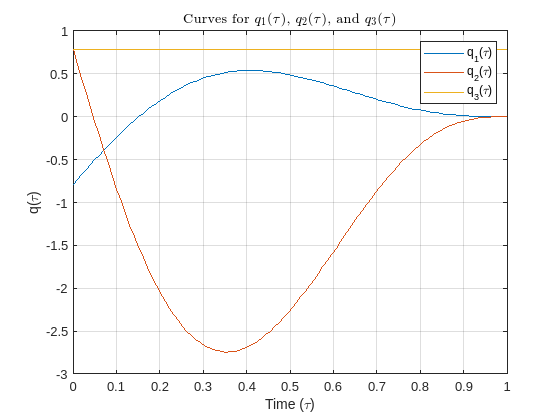



% Create the plot
figure;
plot(tau_values, q_tau_q1_values, 'DisplayName', 'q_{1}(\tau)');
hold on;
plot(tau_values, q_tau_q2_values, 'DisplayName', 'q_{2}(\tau)');
plot(tau_values, q_tau_q3_values, 'DisplayName', 'q_{3}(\tau)');
xlabel('Time (\tau)');
ylabel('q(\tau)');
title('Curves for $$q_{1}(\tau)$$, $$q_{2}(\tau)$$, and $$q_{3}(\tau)$$', 'Interpreter', 'latex');
legend;
grid on;
hold off;

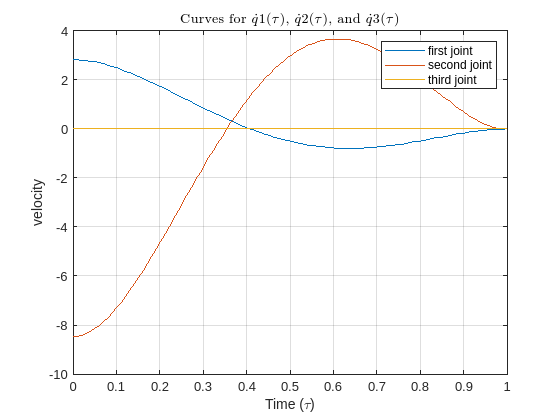



% Create the plot
figure;
plot(tau_values, q_tau_dot_q1_values, 'DisplayName', 'first joint');
hold on;
plot(tau_values, q_tau_dot_q2_values, 'DisplayName', 'second joint');
plot(tau_values, q_tau_dot_q3_values, 'DisplayName', 'third joint');
xlabel('Time (\tau)');
ylabel('velocity');
title('Curves for $$\dot{q}{1}(\tau)$$, $$\dot{q}{2}(\tau)$$, and $$\dot{q}{3}(\tau)$$', 'Interpreter', 'latex');
legend;
grid on;
hold off;

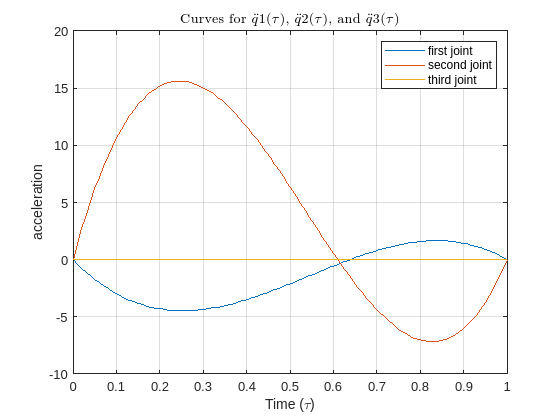


% Create the plot
figure;
plot(tau_values, q_tau_dot_dot_q1_values, 'DisplayName', 'first joint');
hold on;
plot(tau_values, q_tau_dot_dot_q2_values, 'DisplayName', 'second joint');
plot(tau_values, q_tau_dot_dot_q3_values, 'DisplayName', 'third joint');
xlabel('Time (\tau)');
ylabel('acceleration');
title('Curves for $$\ddot{q}{1}(\tau)$$, $$\ddot{q}{2}(\tau)$$, and $$\ddot{q}{3}(\tau)$$', 'Interpreter', 'latex');
legend;
grid on;
hold off;